delta_t = 0.001;
M_1 = 100;
M_2 = 100;
E = zeros(M_1 - 1,M_2 - 1);
B = [0,1;0,1];
N = 1000;

for i = 1:M_1 - 1
    for j = 1:M_2 - 1
        x = [i/M_1,j/M_2];
        E(i,j) = estimation_1(x,N,delta_t,B);
    end
end

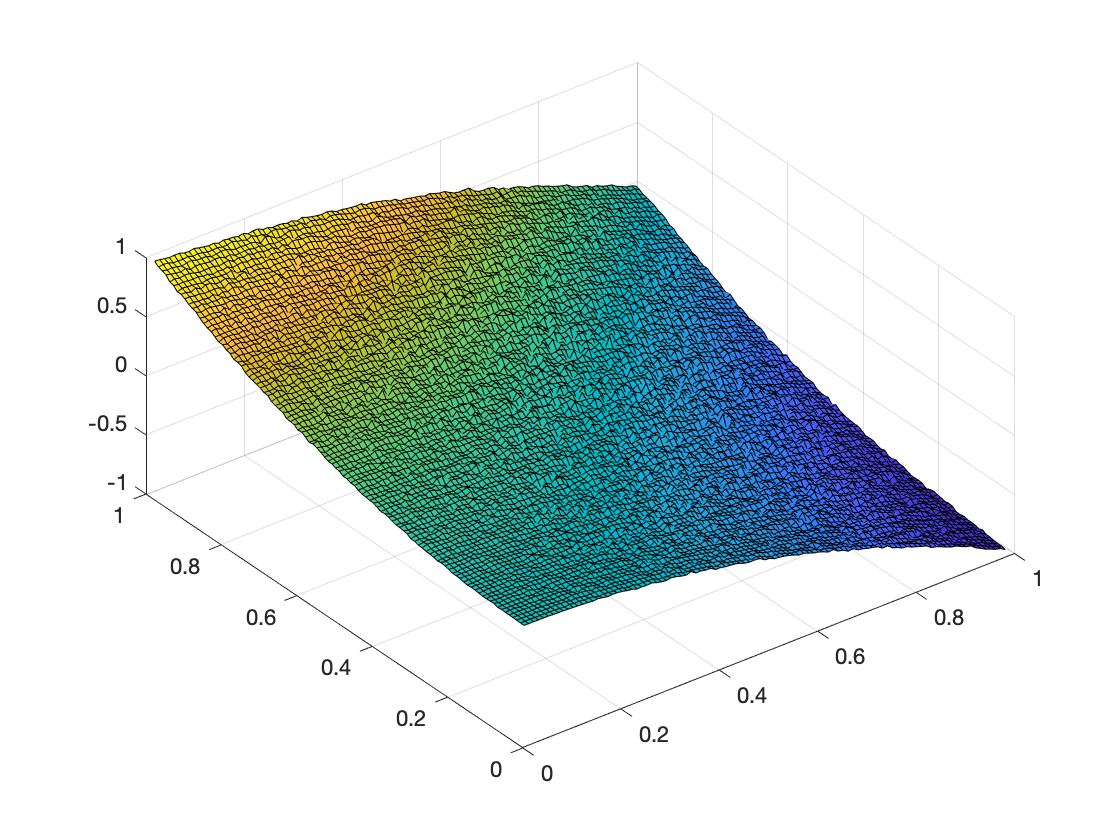

X = (0.01:0.01:0.99);
Y = (0.01:0.01:0.99);
surf(X,Y,E);